%==========================================================================
% Author:    Naghmeh Akhavan, PhD (N. Akhavan)
% Affil.:    University of Michigan
% Contact:   nakhavan@umich.edu
%
% Purpose:
%   Compute and visualize REM propensity in Human sleep cycles after applying
%   an in-place "long-wake DROP" rule, using a 2-component GMM model for the
%   distribution of inter-REM NREM duration |N|.
%
% Core steps:
%   1) Load cycle table (Combined_BigResultTable) and stage-details table
%      (Combined_BigStageDetailsTable).
%   2) Long-wake DROP at the cycle level using contiguous Wake blocks:
%        - For each REM cycle, if any StageDetails row has Stage==WAKE_CODE
%          AND Duration >= WAKE_BREAK_SEC, the entire cycle is dropped.
%   3) Form pooled arrays:
%        - |N| = NREM duration in seconds (N_s)
%        - REMpre in minutes (RP_m) used only for binning
%   4) Split cycles into exactly 4 REMpre bins (for a 2×2 layout) using a
%      custom order-statistic percentile function (no quantile/prctile).
%   5) For each bin and for the lumped data:
%        - Fit a 2-comp GMM to z = log(|N|) (toolbox-free EM; no quantiles)
%        - Compute the GMM-based CDF F(t) for t in seconds
%        - Compute propensity (hazard-like) function:
%            P(t,Δ) = [F(t+Δ) − F(t)] / [1 − F(t)],  Δ = NEAR_FUTURE_SEC
%        - Plot ONLY propensity P(t,Δ), and annotate:
%            (i) first "valley" (local minimum) within a central CDF window
%           (ii) first subsequent "peak" after that valley
%
% Outputs:
%   - Figure 1: 2×2 tiled panels (REMpre bins) with propensity curves
%   - Figure 2: Lumped propensity curve (all kept cycles)
%   - Console tables reporting valley time and peak time (seconds) per panel
%
% Notes:
%   - No quantile/prctile calls: custom percentile is used for REMpre edges.
%   - The GMM is fit in log-space; the CDF is evaluated back in seconds.
%
% Last updated: 2026-01-16
%==========================================================================

clear; clc;


## Paths & knobs

combinedFolder   = 'C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\combined_out';
matR = fullfile(combinedFolder, 'Combined_BigResultTable.mat');
matD = fullfile(combinedFolder, 'Combined_BigStageDetailsTable.mat');

assert(isfile(matR), 'Missing %s.', matR);
assert(isfile(matD), 'Missing %s.', matD);

% Long-wake DROP threshold
WAKE_BREAK_MIN = 2;
WAKE_BREAK_SEC = WAKE_BREAK_MIN*60;

WAKE_CODE = 5;     

% Propensity horizon Delta t (seconds)
NEAR_FUTURE_SEC = 30;

% EXACTLY 4 bins for the 2×2 layout 
NBINS_REM = 4;
assert(NBINS_REM == 4, 'For a 2×2 layout, set NBINS_REM = 4.');

% Histogram bins for small-n fallback
NBINS_HIST = 60;

% CDF search window to avoid extreme tails
CDF_LO = 0.02;
CDF_HI = 0.98;


## Load data

S1 = load(matR);  R = S1.Combined_BigResultTable;
S2 = load(matD);  D = S2.Combined_BigStageDetailsTable;

% Normalize types
R.Subject_Index   = string(R.Subject_Index);
R.REM_Cycle_Index = string(R.REM_Cycle_Index);

% Validate StageDetails schema and normalize types
if ~ismember("Stage", string(D.Properties.VariableNames)), error('Stage column not found in stage table.'); end
if ~ismember("Duration", string(D.Properties.VariableNames)), error('Duration column not found in stage table.'); end
if ~ismember("REM_Cycle_Index", string(D.Properties.VariableNames)), error('REM_Cycle_Index missing in stage table.'); end
D.REM_Cycle_Index = string(D.REM_Cycle_Index);
D.Stage    = double(D.Stage);
D.Duration = double(D.Duration);

% Ensure numeric columns in R
needR = ["REMpre","NREM","Wake","Movement","IREM","REMpost"];
for v = needR
    if ~ismember(v, string(R.Properties.VariableNames)), R.(v) = NaN(height(R),1); end
    R.(v) = double(R.(v));
end
if all(isnan(R.IREM)) && all(ismember(["NREM","Wake","Movement"], string(R.Properties.VariableNames)))
    R.IREM = R.NREM + R.Wake + R.Movement;
end


## Long-wake DROP by cycle

% Preserve within-cycle order and sort
D.ord = (1:height(D))';
D = sortrows(D, {'REM_Cycle_Index','ord'});   % preserve block order

% Group StageDetails rows by REM_Cycle_Index
[Gd, keys] = findgroups(D.REM_Cycle_Index);
hasLongWake = false(numel(keys),1);
% Detect long Wake blocks per cycle
for gi = 1:numel(keys)
    rows = find(Gd==gi);
    st   = D.Stage(rows);
    du   = D.Duration(rows);
    if any(st==WAKE_CODE & du>=WAKE_BREAK_SEC)
        hasLongWake(gi) = true;
    end
end
% sanity check 
FlagTab = table(keys, hasLongWake, 'VariableNames',{'REM_Cycle_Index','HasLongWake'});
R = outerjoin(R, FlagTab, 'Keys','REM_Cycle_Index', 'MergeKeys',true, 'Type','left');

% Drop and report
maskDrop = (R.HasLongWake == 1);
nDrop    = sum(maskDrop, 'omitnan');
Rkeep    = R(~maskDrop, :);
fprintf('Long-wake DROP (Wake >= %d min): dropped %d cycles; kept %d.\n', ...
        WAKE_BREAK_MIN, nDrop, height(Rkeep));

Long-wake DROP (Wake >= 2 min): dropped 1028 cycles; kept 3994.


## Build pooled arrays and REMpre bins

% Extract |N| in seconds and REMpre in minutes
N_s  = Rkeep.NREM;            % |N| in seconds
RP_m = Rkeep.REMpre/60;       % REMpre in minutes (for binning)
% Keep only valid cycles for analysis
valid = isfinite(N_s) & (N_s > 0) & isfinite(RP_m);
N_s   = N_s(valid);
RP_m  = RP_m(valid);
if isempty(N_s), error('No valid cycles after long-wake DROP.'); end


## Compute 4 REMpre-bin edges without quantile/prctile

% Use order-statistic percentile (no quantile/prctile calls):
edgesRP = pctile_noquant(RP_m, linspace(0,1,NBINS_REM+1));
% force strictly increasing edges in case of ties
for i=2:numel(edgesRP)
    if edgesRP(i) <= edgesRP(i-1)
        edgesRP(i) = edgesRP(i-1) + 1e-6;
    end
end
binID = discretize(RP_m, edgesRP);   % 1..4


## Define the GMM + CDF + propensity machinery

% Standard normal CDF helper
Phi = @(u) 0.5*(1+erf(u./sqrt(2)));  % normal CDF
% GMM-based CDF in seconds
gmm_cdf_seconds = @(t, w, mu, sd) ...
    arrayfun(@(tt) sum(w .* Phi((log(max(tt,eps)) - mu)./sd)), t(:)).';

% GMM fitter (2 components; no quantiles)
fit2_noquant = @(z) fit_gmm_1d_noquant(z, 2, struct('nStarts',30,'maxIter',200,'tol',1e-6, ...
                                                    'trimFrac',0.01,'sdMin',0.08,'sdMax',3.0));


## Figure 1: 2*2 REMpre-bin propensity panels

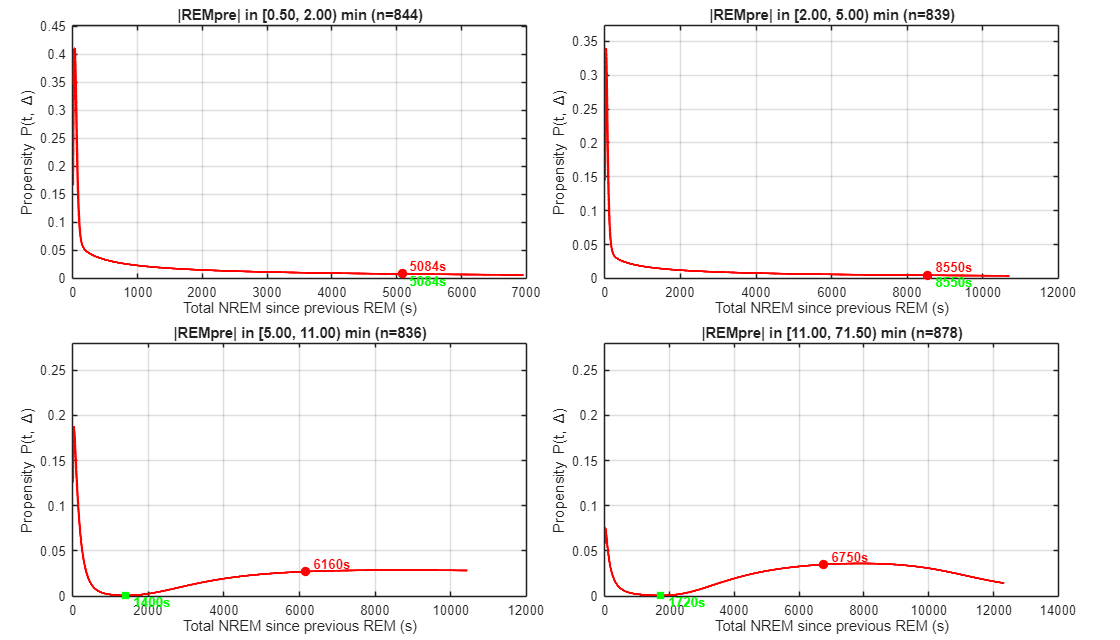

fBins = figure('Color','w','Position',[120 80 1120 640]);
tlBins = tiledlayout(2,2,'TileSpacing','compact','Padding','compact');

% Arrays to store extrema per bin
lastLocalMax_bins = NaN(NBINS_REM,1);
globalMin_bins    = NaN(NBINS_REM,1);

% loop through bins and plot each panel
for b = 1:NBINS_REM
    ax = nexttile(tlBins);
    inBin = (binID == b);
    Nb_s  = N_s(inBin);
    a = edgesRP(b); bnd = edgesRP(b+1);
    titleStr = sprintf('|REMpre| in [%.2f, %.2f) min', a, bnd);

    [lastLocalMax_bins(b), globalMin_bins(b)] = plot_panel(ax, Nb_s, titleStr, ...
        NEAR_FUTURE_SEC, CDF_LO, CDF_HI, NBINS_HIST, fit2_noquant, gmm_cdf_seconds);
end

## Figure 2: Lumped propensity (all kept cycles)

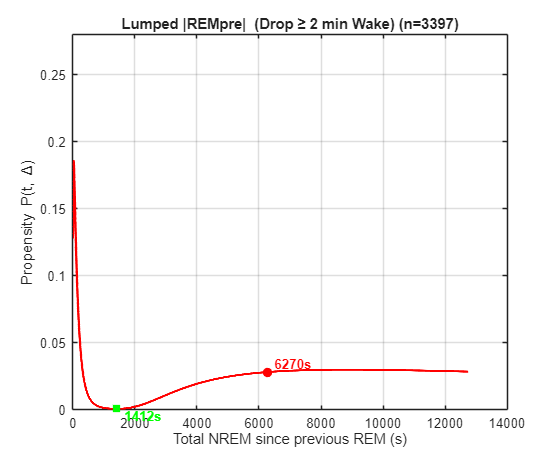

% creat lumped figure and plot
fLumped = figure('Color','w','Position',[160 120 560 460]);
axL = axes(fLumped);
[lastLocalMax_lumped, globalMin_lumped] = plot_panel(axL, N_s, ...
    sprintf('Lumped |REMpre|  (Drop ≥ %d min Wake)', WAKE_BREAK_MIN), ...
    NEAR_FUTURE_SEC, CDF_LO, CDF_HI, NBINS_HIST, fit2_noquant, gmm_cdf_seconds);


% sgtitle(fLumped, sprintf('Propensity — Lumped (Δt = %d s)', NEAR_FUTURE_SEC), ...
%         'FontWeight','bold', 'Interpreter','none');


## Report extrema as tables

% package bin results
binNames = arrayfun(@(i) sprintf('Bin %d', i), 1:NBINS_REM, 'UniformOutput', false).';
T_bins   = table(binNames, lastLocalMax_bins, globalMin_bins, ...
    'VariableNames', {'Panel','Last_Local_Max_s','Global_Min_s'});
% package lumped results
T_lump   = table(string("Lumped"), lastLocalMax_lumped, globalMin_lumped, ...
    'VariableNames', {'Panel','Last_Local_Max_s','Global_Min_s'});
% display
disp('--- Extrema for bins (seconds) ---');   disp(T_bins);

--- Extrema for bins (seconds) ---
      Panel      Last_Local_Max_s    Global_Min_s
    _________    ________________    ____________

    {'Bin 1'}          5084              5084    
    {'Bin 2'}          8550              8550    
    {'Bin 3'}          6160              1400    
    {'Bin 4'}          6750              1720    



disp('--- Extrema for lumped (seconds) ---'); disp(T_lump);

--- Extrema for lumped (seconds) ---
     Panel      Last_Local_Max_s    Global_Min_s
    ________    ________________    ____________

    "Lumped"          6270              1412    



## Functions

% pctile_noquant: Computes percentiles using sorted order statistics and linear interpolation
% fit_gmm_1d_noquant: Toolbox-free EM fit for 1D K-component Gaussian mixture
% em_core: Core EM loop
% first_valley_then_peal: Finds (1) first local minimum in the search
% window (2) first local maximum occurring at least minSepSec after the minimum
% plot_panel: This function: fit GMM → compute F(t) → compute propensity → plot → annotate

function v = pctile_noquant(x, pvec)
% Order-statistic percentile without quantile/prctile.
% pvec in [0,1]. Linear interpolation between neighbors.
    x = x(:); x = x(isfinite(x));
    x = sort(x);
    n = numel(x);
    if n==0, v = NaN(size(pvec)); return; end
    v = zeros(size(pvec));
    for i=1:numel(pvec)
        p = min(max(pvec(i),0),1);
        if n==1, v(i)=x; continue; end
        pos = 1 + p*(n-1);
        lo  = floor(pos); hi = ceil(pos);
        if lo==hi
            v(i) = x(lo);
        else
            w = pos - lo;
            v(i) = (1-w)*x(lo) + w*x(hi);
        end
    end
end

function [w, mu, sd, info] = fit_gmm_1d_noquant(x, K, opts)
% EM for 1-D K-Gaussian mixture WITHOUT quantile/prctile.
    x = x(:); x = x(isfinite(x));
    if nargin<3, opts = struct; end
    g = @(f,d) (isfield(opts,f)&&~isempty(opts.(f))) * opts.(f) + (~isfield(opts,f)||isempty(opts.(f))) * d;
    nStarts  = g('nStarts',20); maxIter = g('maxIter',300); tol = g('tol',1e-6);
    trimFrac = g('trimFrac',0.0); sdMin = g('sdMin',0.08); sdMax = g('sdMax',3.0);

    muX = mean(x); sdX = std(x);
    if isfinite(sdX) && sdX>0
        lo = muX - 6*sdX; hi = muX + 6*sdX;   % mild outlier guard
        x = x(x>=lo & x<=hi);
    end
    n = numel(x);

    log2pi = log(2*pi); bestLL = -inf; best = [];
    base_mu = muX + 0.5*sdX*linspace(-1,1,K);
    base_sd = max(sdMin, 0.3*max(sdX,eps))*ones(1,K);
    base_w  = ones(1,K)/K;

    for s=1:nStarts
        mu0 = base_mu + 0.10*max(sdX,eps)*randn(1,K);
        sd0 = max(sdMin, min(sdMax, base_sd));
        w0  = base_w;
        [w1, mu1, sd1, LL] = em_core(x, w0, mu0, sd0, maxIter, tol, trimFrac, sdMin, sdMax, log2pi);
        if LL(end) > bestLL, bestLL = LL(end); best = {w1,mu1,sd1,LL}; end
    end
    [w, mu, sd, LL] = best{:};
    info = struct('loglik',LL,'nStarts',nStarts,'n',n);
end

function [w, mu, sd, LL] = em_core(x, w, mu, sd, maxIter, tol, trimFrac, sdMin, sdMax, log2pi)
    n = numel(x); K = numel(w); LL = zeros(maxIter,1); trimN = floor(trimFrac*n);
    for it=1:maxIter
        % E-step
        logp = zeros(n,K);
        for k=1:K
            v = sd(k)^2;
            logp(:,k) = -0.5*log2pi - 0.5*log(v) - (x-mu(k)).^2/(2*v) + log(max(w(k),eps));
        end
        m = max(logp,[],2); P = exp(logp - m); s = sum(P,2); gamma = P ./ max(s,eps);

        if trimN>0, [~,idx]=sort(s,'ascend'); keep=true(n,1); keep(idx(1:trimN))=false; else, keep=true(n,1); end

        Nk = sum(gamma(keep,:),1);
        w  = Nk ./ max(sum(Nk),eps); w = max(w,1e-4); w = w/sum(w);
        for k=1:K
            mu(k) = sum(gamma(keep,k).*x(keep)) / max(Nk(k),eps);
            v     = sum(gamma(keep,k).*(x(keep)-mu(k)).^2) / max(Nk(k),eps);
            sd(k) = sqrt(max(sdMin^2, min(v, sdMax^2)));
        end

        % log-likelihood (on kept)
        xk = x(keep); nk = numel(xk);
        logp = zeros(nk,K);
        for k=1:K
            v = sd(k)^2;
            logp(:,k) = -0.5*log2pi - 0.5*log(v) - (xk-mu(k)).^2/(2*v) + log(max(w(k),eps));
        end
        m = max(logp,[],2);
        LL(it) = sum(m + log(sum(exp(logp - m),2)));
        if it>1 && abs(LL(it)-LL(it-1)) < tol*max(1,abs(LL(it-1))), LL = LL(1:it); break; end
    end
    LL = LL(1:it);
end

function [imin, imax] = first_valley_then_peak(Ps, searchMask, minSepSec, minProm)
% Find first local min in search window, then first peak after it.
    Ps = Ps(:)'; N  = numel(Ps);
    idx = find(searchMask);
    if isempty(idx), imin=NaN; imax=NaN; return; end
    lo = idx(1); hi = idx(end);

    mins = islocalmin(Ps, 'MinProminence', minProm);
    candMin = find(mins & (1:N)>=lo & (1:N)<=hi);
    if isempty(candMin)
        [~,ii] = min(Ps(lo:hi)); imin = lo+ii-1;
    else
        imin = candMin(1);
    end

    start = min(hi, imin + max(1, round(minSepSec)));
    maxs = islocalmax(Ps, 'MinProminence', minProm);
    candMax = find(maxs & (1:N)>=start & (1:N)<=hi);
    if isempty(candMax)
        [~,jj] = max(Ps(start:hi)); imax = start+jj-1;
    else
        imax = candMax(1);
    end
end

function [tLastMax, tGlobMin] = plot_panel(ax, Nbin_s, titleStr, ...
        NEAR_FUTURE_SEC, CDF_LO, CDF_HI, NBINS_HIST, fit2_fun, gmm_cdf_seconds)

    axes(ax); cla(ax);

    z = log(Nbin_s(:)); z = z(isfinite(z));
    if numel(z) < 20
        histogram(Nbin_s, min(NBINS_HIST, max(10, round(numel(Nbin_s)/3))), ...
            'Normalization','pdf','FaceAlpha',0.2,'EdgeColor',[0.2 0.2 0.2]);
        title(sprintf('%s (n=%d)\n[too few for GMM]', titleStr, numel(Nbin_s)));
        grid on; box on; tLastMax=NaN; tGlobMin=NaN; return;
    end
    [w, mu, sd] = fit2_fun(z);

    % Robust tMax without prctile: mean + 6*std, clamped
    mN = mean(Nbin_s,'omitnan'); sN = std(Nbin_s,'omitnan');
    tMax = round(max(NEAR_FUTURE_SEC+5, min(max(Nbin_s), mN + 6*max(sN,1))));
    tMax = min(tMax, 20000);
    t    = 1:tMax;

    F    = gmm_cdf_seconds(t, w, mu, sd);                 % not plotted
    Ftau = gmm_cdf_seconds(t + NEAR_FUTURE_SEC, w, mu, sd);
    P    = (Ftau - F) ./ max(1 - F, eps);

    searchMask = (F >= CDF_LO) & (F <= CDF_HI) & (t <= tMax - NEAR_FUTURE_SEC);

    Ps = P; if numel(Ps) >= 21, Ps = movmean(Ps, 21, 'omitnan'); end
    MIN_SEP_SEC = 60; MIN_PROM = 0.002;
    [imin, imax] = first_valley_then_peak(Ps, searchMask, MIN_SEP_SEC, MIN_PROM);
    tGlobMin = imin; tLastMax = imax;

    % -------- PLOT ONLY PROPENSITY --------
    plot(t, P, 'r-', 'LineWidth', 1.8); hold on;
    ylabel('Propensity P(t, \Delta)');
    Pf = P(isfinite(P)); pMax = 0; if ~isempty(Pf), pMax = max(Pf); end
    ylim([0, max(0.28, min(0.5, 1.1*pMax))]);

    xlabel('Total NREM since previous REM (s)');
    title(sprintf('%s (n=%d)', titleStr, numel(Nbin_s)));

    if ~isnan(tGlobMin)
        scatter(t(tGlobMin), P(tGlobMin), 50, 'g', 'filled', 's');
        text(t(tGlobMin), P(tGlobMin), sprintf('  %ds', t(tGlobMin)), ...
            'Color','g','FontWeight','bold','VerticalAlignment','top');
    end
    if ~isnan(tLastMax)
        scatter(t(tLastMax), P(tLastMax), 50, 'r', 'filled');
        text(t(tLastMax), P(tLastMax), sprintf('  %ds', t(tLastMax)), ...
            'Color','r','FontWeight','bold','VerticalAlignment','bottom');
    end
    grid on; box on;
end
